# Hypothesis testing 

During this session, you will learn the difference false negatives and false positives, bootstrapping, and permutation. These concepts will tell you certain details of your data and how you can make your hypothesis testing more robust. 

- Generating testable hypothesis (concept)

- False negatives and false positives (concept)

- Generating / simulating data (with practical component)

- Performing permutation and bootstrap type tests using the simulated data

- Plotting your results following permutation-type tests (determining noise level)

## Hypothesis and p-value

In general there are two kinds of hypothesis: 

- one general one for your career/broader view. 

- a more testable hypothesis.

During this session we will focus on the second type of hypothesis. 

Before you start testing your hypothesis, you need to make sure that you comparing two good distributions of your data, or one distribution with the Null distribution. The [p-value](https://en.wikipedia.org/wiki/P-value)  is the probability that, using a given statistical model, the statistical summary (such as the sample mean difference between two compared groups) would be the same as or more extreme than the actual observed results. Due to incomplete knowledge of statistics, reliability and reproducibility are under scrutinity. A major cause of this lack of repeatability is not being  considered: the wide sample-to-sample variability in the p-value. The paper of Halsey *et al *explain why the p-value is fickle to discourage the ill-informed practice of interpreting analyses based predominantly on this statistic ([Halsey et al. (2015), Nature Reviews ](http://www.nature.com/nmeth/journal/v12/n3/abs/nmeth.3288.html)).

The main causes of variability in p-value is caused by: 

- sample size. This should be sufficiently big to approach a reliable distribution.

- know your biases in sample.

- effect sizes, confidence intervals, likelihood ratio (basically, know your data!)

## Type I and type II errors

In statistical hypothesis testing, a **type I error** is the incorrect rejection of a true null hypothesis (a "false positive"), while a **type II error** is incorrectly retaining a false null hypothesis (a "false negative"). The sample size small is crucial here as it biases the outcome to [type I or type II error](https://en.wikipedia.org/wiki/Type_I_and_type_II_errors).

- Type I error: detecting the effect when there is none > false positive

- Type II error: missing the effect when there is > false negative

We will start generating and simulating data, for which we use several different distributions.

Create a *Gaussian* distribution

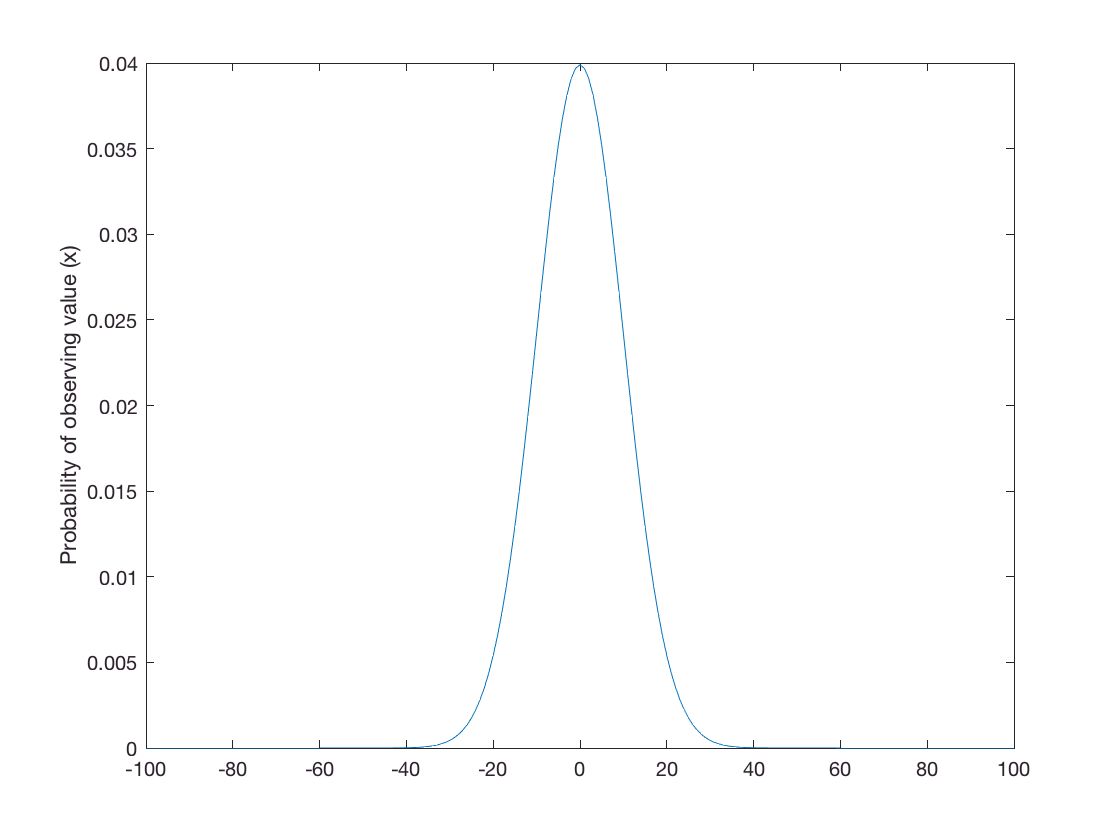

gauss = makedist('Normal', 'mu', 0, 'sigma', 10);
gauss_distribution = pdf(gauss, -100:100);
figure;
plot(-100:100, gauss_distribution)
ylabel('Probability of observing value (x)');

Create a *Poisson *distribution

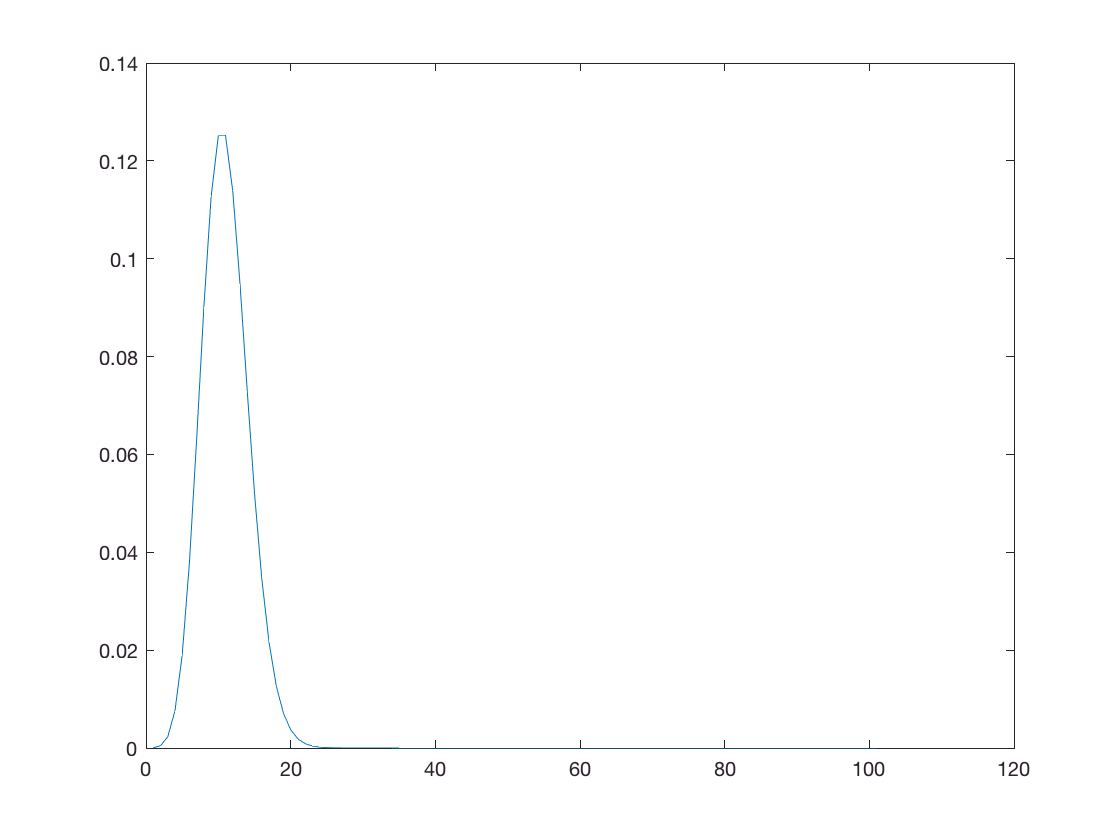

poisson = makedist('Poisson', 'lambda', 10);
poisson_distribution = pdf(poisson, 0:100);
figure;
plot(poisson_distribution);

Here you see the effect of increasing the sample size in a Poisson distribution. This turns the Poisson distribution into Normal distribution.

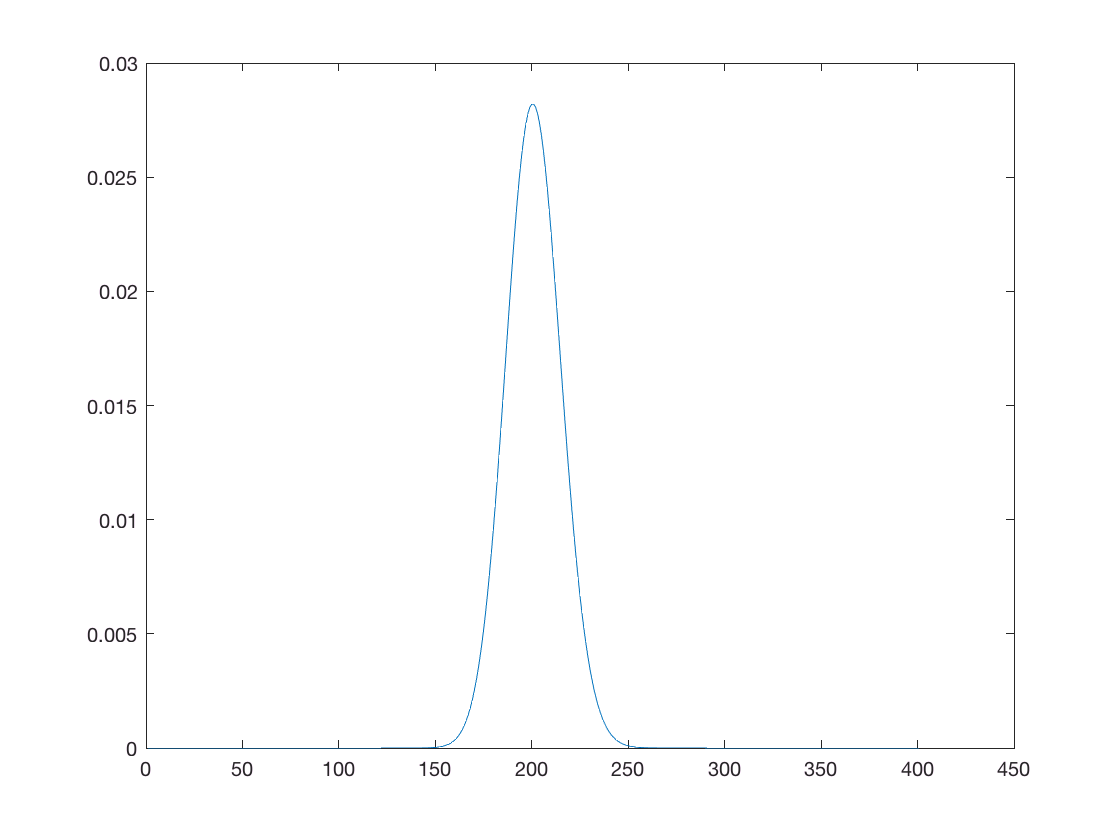

poisson = makedist('Poisson', 'lambda', 200); % change lambda parameter to see what happens with the distribtion
poisson_distribution = pdf(poisson, 0:400);
figure;
plot(poisson_distribution)

The [Weibull distribution](https://en.wikipedia.org/wiki/Weibull_distribution) is a continuous probability distributio and has a shape parameter *k*, and a scale parameter λ > 0. 

- When k < 1, the failure rate decreases over time. This happens if there is significant "infant mortality", or defective items failing early and the failure rate  decreasing over time as the defective items are weeded out of the  population;

- When k = 1, the failure rate is constant over time. This might  suggest random external events are causing mortality, or failure. The Weibull distribution reduces to an exponential distribution;

- When k > 1, the failure rate increases with time. This happens if  there is an "aging" process, or parts that are more likely to fail as time goes on.

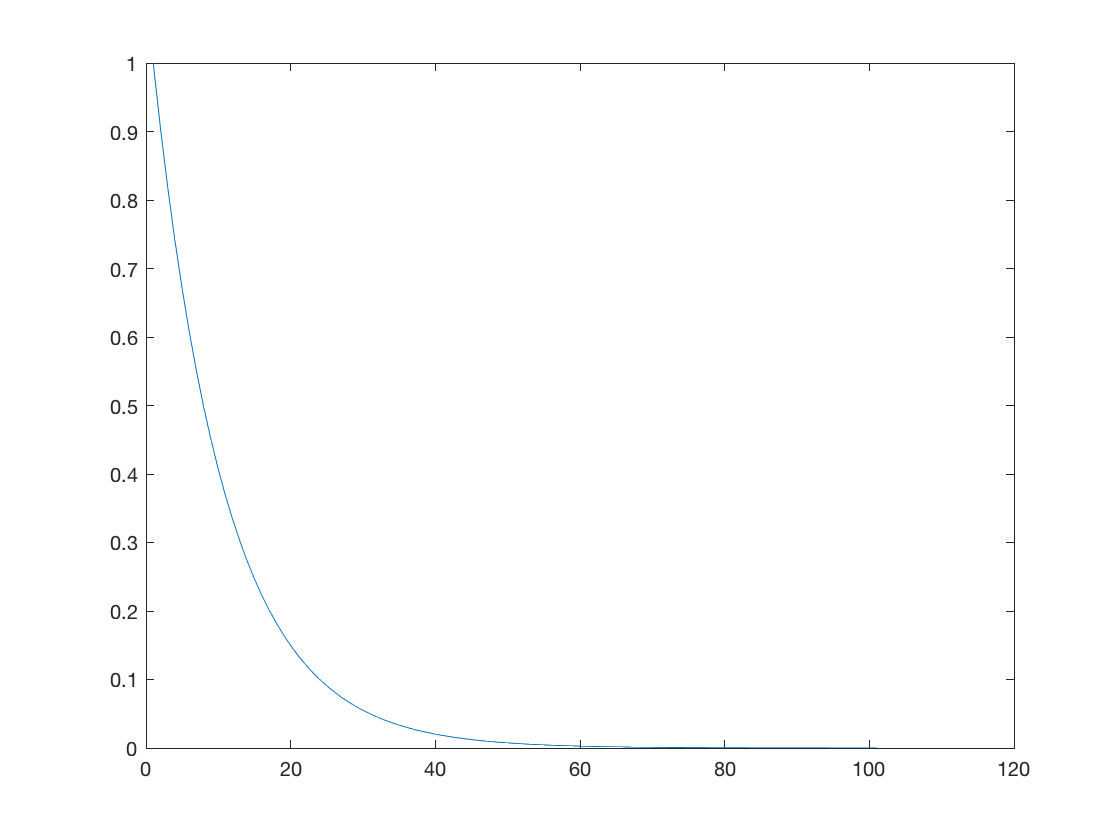

weibull = makedist('Weibull', 'a', 1, 'b', 1); % a is the shape value k. Change this variable to see the effect of the distribution
weibull_distribution = pdf (weibull, 0:.1:10);
figure;
plot(weibull_distribution)

## Resampling

In statistics, [resampling](https://en.wikipedia.org/wiki/Resampling_(statistics)) is a method for estimating the sampling distribution of an estimator by sampling with replacement from the original sample, most often with the purpose of deriving robust estimates of standard errors and confidence intervals of a population parameter like a mean, median, proportion, odds ratio, correlation coefficient or regression coefficient. The following techinques can be applied:

- **bootstrap**: is estimating the precision of sample statistics (medians, variances, percentiles) by drawing randomly with replacement from a set of data points

- **jackknifing**: is estimating the precision of sample statistics (medians, variances, percentiles) by using subsets of available data

- **permutation**: exchanging labels on data points when performing significance tests > noise level distribution as you get rid of the labels

- **cross-validation**: validating models by using random subsets

In this session, we will focus on bootstrapping and permutation.

## Bootstrap

Here we use [Bootstrap](https://en.wikipedia.org/wiki/Bootstrapping) and simulate responses of two neurons: cell A and cell B.

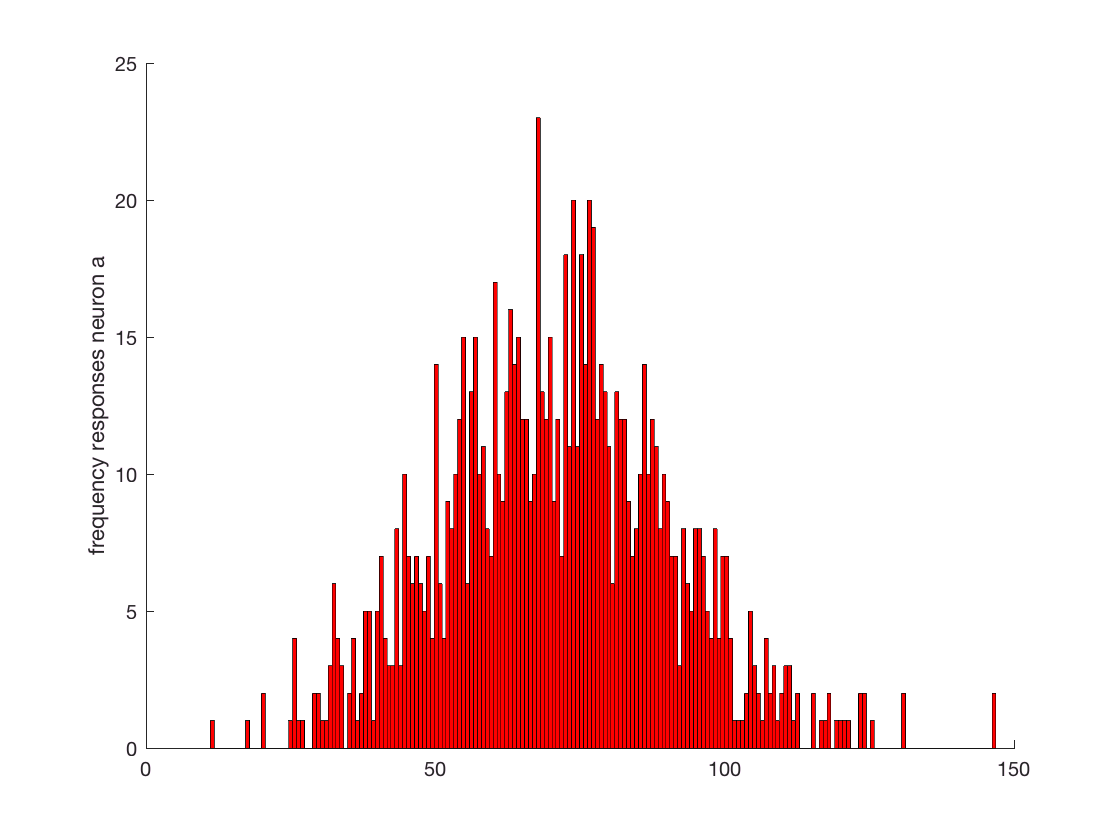

mean_rate_a = 70;
std_rate_a = 20;

mean_rate_b = 60;
std_rate_b = 20;

noise = 0;

n_samples = 1000;
step_by = 5;

figure;
hold on

% get response vectors for neuron a and b
responses_a = std_rate_a .* randn(n_samples, 1) + mean_rate_a; % .* is element-wise multiplication 
responses_b = std_rate_b .* randn(n_samples, 1) + mean_rate_b;

%plot a histogram of the binned responses
hist(responses_a, floor(n_samples/5)); %how many bins? floor(n_sample/5)
set(get(gca, 'child'), 'FaceColor', 'r', 'EdgeColor', 'k');
ylabel('frequency responses neuron a')

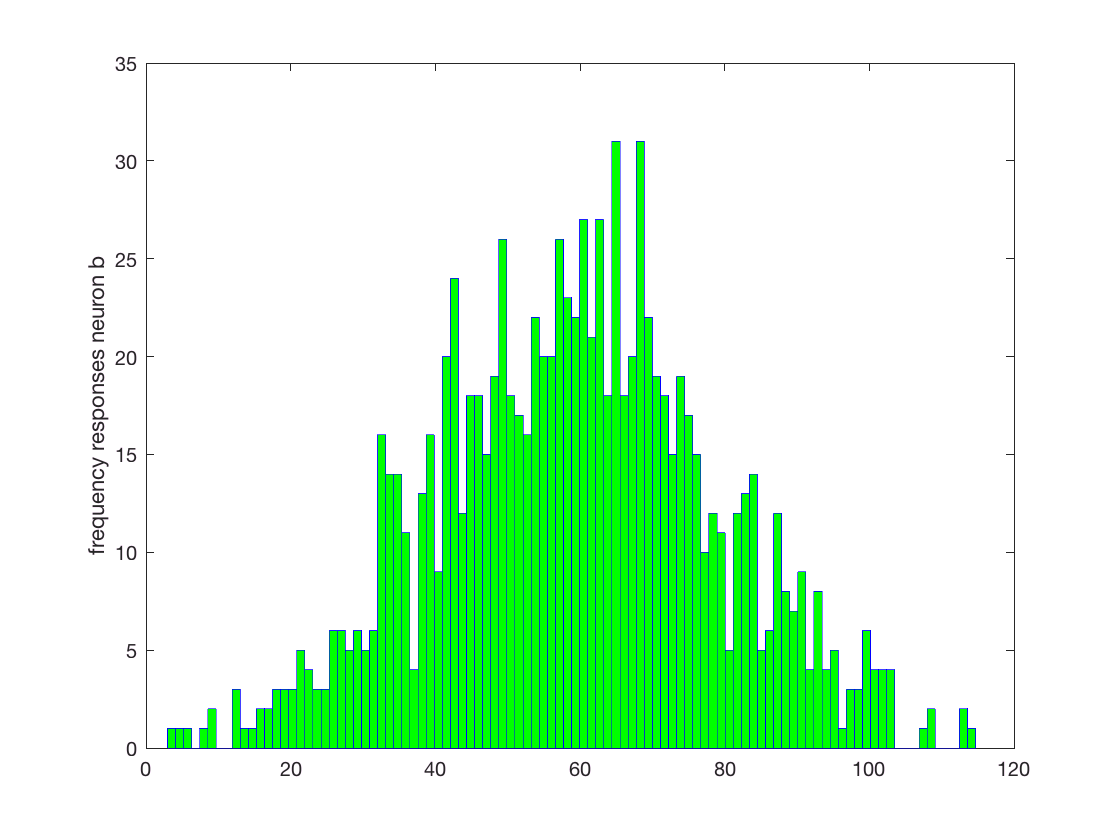


figure;
hist(responses_b, floor(n_samples/10)); % how many bins? floor(n_sample/5)
set(get(gca, 'child'), 'FaceColor', 'g', 'EdgeColor', 'b');
ylabel('frequency responses neuron b')

hold off

Bootstrap to see if cell A's response vector is significantly greater than cell B. 

n_repetitions = 1000; % how many times do we want
a_greater_than_b = zeros(1, n_repetitions); % make arrays to fill in the repetitions

responses_both = [responses_a; responses_b]; % draw from combined distribution

for i = 1:n_repetitions
    
    % y = datasample (data,k) returns k observations sampled uniformly at random, with replacement, from the data.
    %resampled_responses_a = datasample(responses_a, numel(responses_a));
    %resampled_responses_b = datasample(responses_b, numel(responses_b));
    
    resampled_responses_a = datasample(responses_both, numel(responses_a));
    resampled_responses_b = datasample(responses_both, numel(responses_b));
    
    mean_a = mean(resampled_responses_a);
    mean_b = mean(resampled_responses_b);
    
    a_greater_than_b(i) = mean_a > mean_b;
end

% calculating p-value 
p = 1 - sum(a_greater_than_b)/n_repetitions

p = 0.5320


% For t-test you can use ttest2 in MatLab, which is default to two sided test.
[h p] = ttest2(responses_a, responses_b)

h = 1

p = 1.2744e-39

## Permutation test

Here we use the [permutation test](http://thomasleeper.com/Rcourse/Tutorials/permutationtests.html) to permute the response of a single neuron to condition A and B.

Let's plot a new distribution centered around zero, and perform a shuffling test to see what would be the noise distribution, and whether the real distribuiton is above the chance level. 

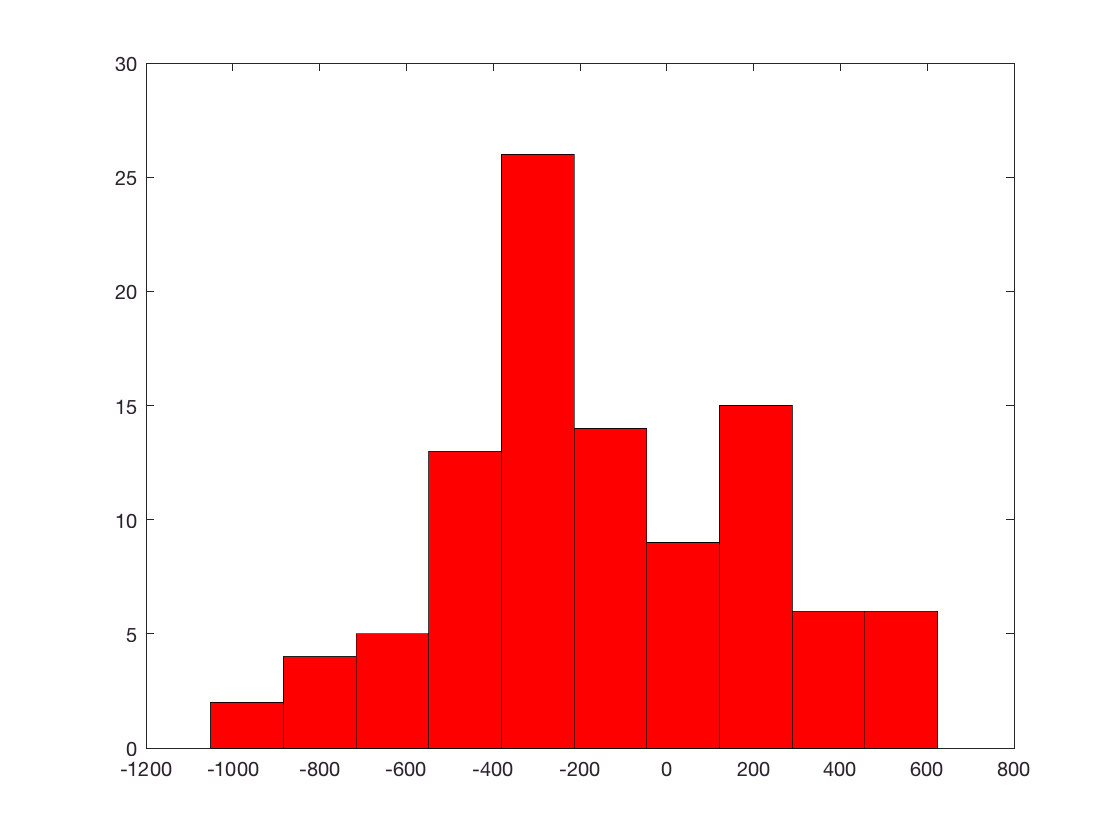

mean_rate_condition1 = 1e3 - 100;
std_rate_condition1 = 300;
mean_rate_condition2 = 1e3;
std_rate_condition2 = 300;
n_samples = 100;
n_permutations = 1000;

% starting mean scaled by std + random offset
%responses_cnd1 = std_rate_condition1 .* randn(n_samples, 1) + mean_rate_condition1;
%responses_cnd2 = std_rate_condition2 .* randn(n_samples, 1) + mean_rate_condition2;

% normrnd that take mu and std as arguments
responses_cnd1 = normrnd(mean_rate_condition1, std_rate_condition1, n_samples, 1);
responses_cnd2 = normrnd(mean_rate_condition2, std_rate_condition2, n_samples, 1);

%responses_cnd1 = responses_cnd1(:);
%responses_cnd2 = responses_cnd2(:);

index_cnd1 = true(size(responses_cnd1)); % set labels for permuting
index_cnd2 = false(size(responses_cnd2));

responses_all_cnds = [responses_cnd1; responses_cnd2];
indices_all_cnds = [index_cnd1; index_cnd2]; % same format as the responses

figure;
hist(responses_cnd1 - responses_cnd2);
set(get(gca, 'child'), 'FaceColor', 'r', 'EdgeColor', 'k');

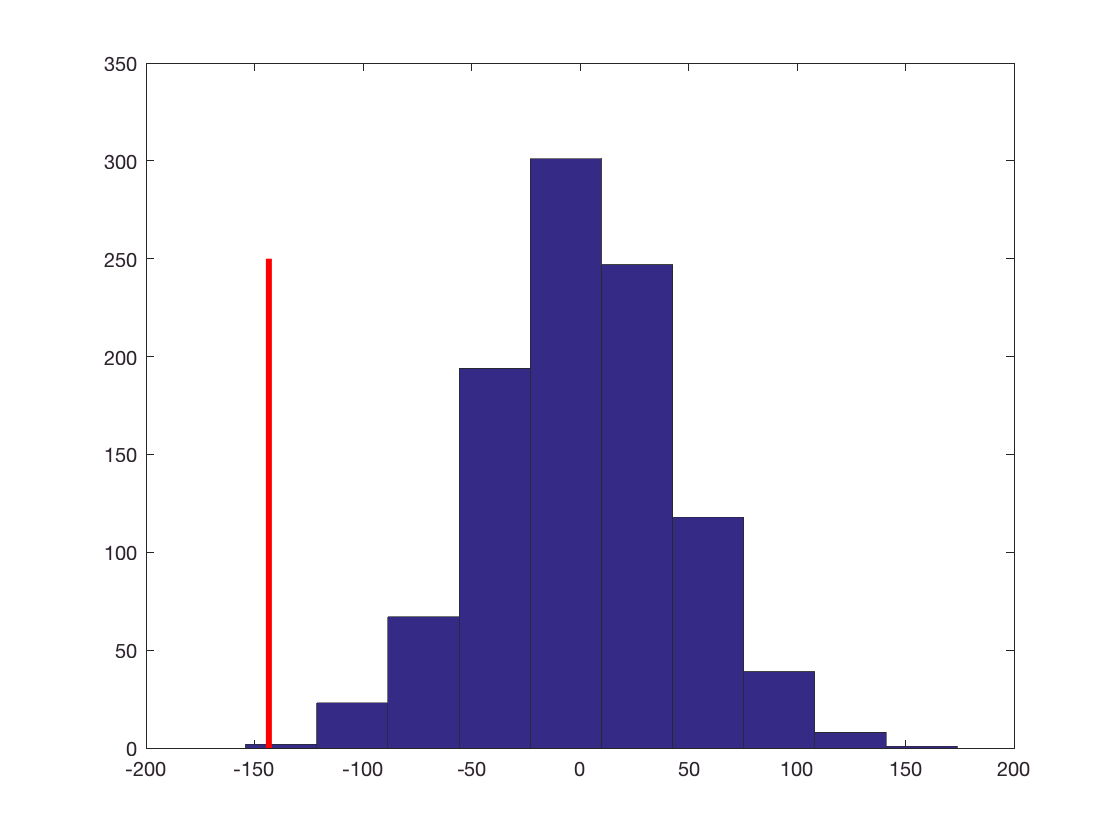

% is this different from 0
mean(responses_cnd1 - responses_cnd2);

% is this different from noise distribution
observed_difference = mean(responses_cnd1) - mean(responses_cnd2);
permuted_was_greater = zeros(1, n_permutations);
means = zeros(1,n_permutations);

for i = 1:n_permutations
    % numel(indices_all_cnds) gives you the length
    % randperm(x) gives you random number for each that is less than x
    % indices_all_cnds (randperm ...) gives you a new mapping of 0 and 1
    
    indices_all_cnds = indices_all_cnds(randperm(numel(indices_all_cnds)));
    
    resampled_responses_cnd1 = responses_all_cnds(indices_all_cnds); % gives all values that matches 1. This always changes on repeat.
    resampled_responses_cnd2 = responses_all_cnds(~indices_all_cnds); % gives all values that match 0
    
    means(i) = mean(resampled_responses_cnd1) - mean(resampled_responses_cnd2);
    
    permuted_was_greater(i) = means(i) > observed_difference;
end

p = 1 - sum(permuted_was_greater / n_permutations);

figure;
hist(means);
hold on
plot([observed_difference;observed_difference], [0;250], 'r', 'linewidth', 3)


[h p] = ttest2(responses_cnd1,responses_cnd2)

h = 1

p = 7.9301e-04